clear all
rng(1); % for reproducibility added after the results in the report however
data = readtable("G20CrNi2Mo Bearing Steel Data_Zhao.xlsx");

%data.Properties.VariableNames
%unique(data.ContactStressAmplitude_MPa_);
%groupcounts(data, "ContactStressAmplitude_MPa_"); 

S_data = data.ContactStressAmplitude_MPa_;
N_data = data.NumberOfCycles;
stress_levels = unique(S_data);
num_stress_levels = numel(stress_levels);

% quantile regression to get the median relationship at the nominal stresses
log_stress_data = log10(S_data);
Y = log10(N_data);

% matlab checks because of issues with quantile reg
%size(log_stress_data)
%size(log_life_data)
%[min(log_stress_data) max(log_stress_data)]
%[min(log_life_data) max(log_life_data)]
%corrcoef(log_stress_data, log_life_data)

% linear quantile regression for 50% quantile, which gives B50 (distribution-less)
mdl = fitrqlinear(log_stress_data, Y, Quantiles=0.50, Lambda=0,Standardize=true, BetaTolerance=1e-6) % order matters here, the predictor is the log-stress and the response is log-life

mdl =   RegressionQuantileLinear
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
                     Beta: -0.3828
                     Bias: 7.7525
                Quantiles: 0.5000



slope_coefficient = mdl.Beta

slope_coefficient = -0.3828

intercept = mdl.Bias

intercept = 7.7525

mdl.ConvergenceInfo % required because of convergence issues, had to include standardize = true for proper run

ans = struct with fields:
                  Lambda: 0
               Objective: 0.2050
          IterationLimit: 1000
           NumIterations: 8
            GradientNorm: 3.6097e-18
       GradientTolerance: 1.0000e-06
    RelativeChangeInBeta: 4.2730e-04
           BetaTolerance: 1.0000e-06
         TerminationCode: 2
       TerminationStatus: {'Tolerance on gradient satisfied.'}
                 History: []
                 FitTime: 0.2054



% generate the B50 Y points 
B50_predictions = predict(mdl, log_stress_data); % to ensure s-n curve matches up with data, due to standardise

residuals = Y - B50_predictions;

% Defines the input distributions 
% residual statistics - normally distributed for lognormal fatigue life model 
mu_e = 0; % define this as zero as median of normal dist = mean, and median is approx zero
sigma_e = std(residuals);

% minimum extreme-value distribution for Weibull fatigue life model
params_ev = evfit(residuals);
mu_ev = params_ev(1);
sigma_ev = params_ev(2);

% Sobol for global sensitivity analysis - for 2P Lognormal and 2P Weibull fatigue life models 
% Analysis parameters

N = 500000 % number of mc base samples 

N = 500000

n_params = 2 % number of input parameters (load and material)

n_params = 2

params_string = ["Load uncertainty" "Material scatter"]';

results_stress = [];
results_model = strings(0,1);
results_input = strings(0,1);
results_first = [];
results_total = [];

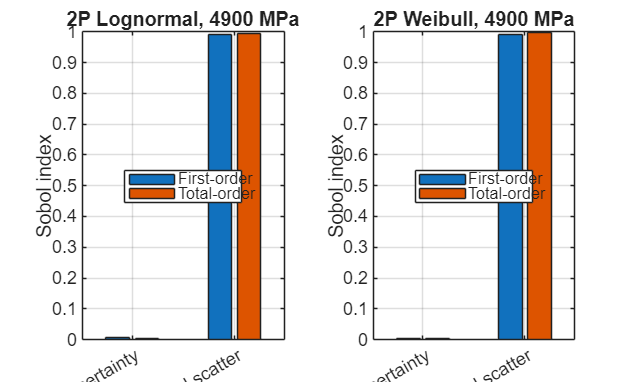

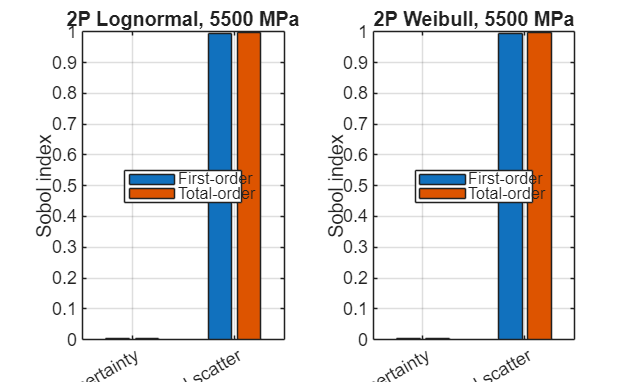

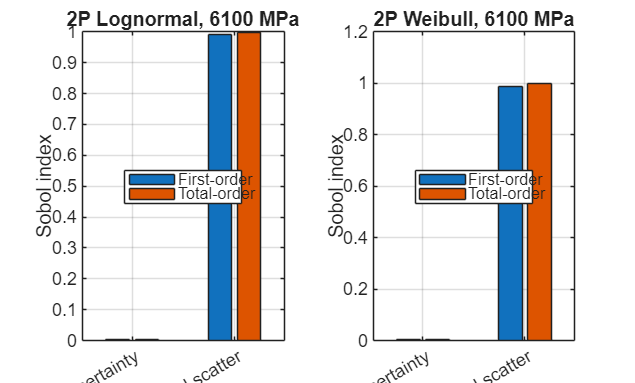

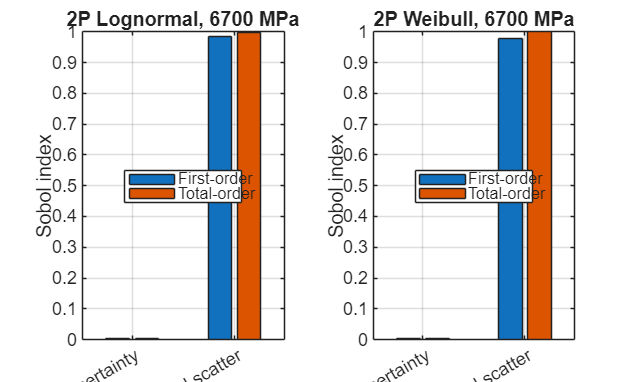


for s = 1:num_stress_levels

    S_nom = stress_levels(s); % nominal stress level 
    cov_S = 0.01; % coefficient of variance for stress 
    sigma_S = cov_S * S_nom; % standard deviation at nominal stress 
    mu_S = S_nom;

    % generate matrices A and B (independent) with random numbers populating them - uniformly distributed 
    U_A = rand(N, n_params);
    U_B = rand(N, n_params);

    % transform Sobol samples into normal input distributions
    A = zeros(N, n_params);
    B = zeros(N, n_params);

    A(:,1) = norminv(U_A(:,1), mu_S, sigma_S); % column 1 is load 
    A(:,2) = norminv(U_A(:,2), mu_e, sigma_e); % column 2 is material  

    B(:,1) = norminv(U_B(:,1), mu_S, sigma_S);
    B(:,2) = norminv(U_B(:,2), mu_e, sigma_e);

    % matrix generation diagnostics 
    %A
    %B
    %mean(A(:,1))
    %std(A(:,1))
    %mean(A(:,2))
    %std(A(:,2))

    Y_A = predict(mdl, log10(A(:,1))) + A(:,2); % Y is log_10(N)
    Y_B = predict(mdl, log10(B(:,1))) + B(:,2);

    % further diagnostics - mean(Y_A) and mean (Y_B) should be approx the same,
    % and so should the std values since A and B were independently generated from same input dist
    %mean(Y_A)
    %std(Y_A)
    %mean(Y_B)
    %std(Y_B)

    % hybrid matrix AB_load - load from matrix B replaces load in matrix A, material scatter column remain unchanged  
    AB_load = A;
    AB_load(:,1) = B(:,1);
    Y_AB_load = predict(mdl, log10(AB_load(:,1))) + AB_load(:,2); 

    % hybrid matrix AB_material - material scatter from matrix B replaces material scatter in matrix A, load is unchanged 
    A_B_material = A;
    A_B_material(:,2) = B(:,2);
    Y_AB_material = predict(mdl, log10(A_B_material(:,1))) + A_B_material(:,2);

    % first order indices (using Saltelli estimator)
    varY_A = var(Y_A, 1); % this is an approx. to the var(Y) in the equation from Asgheri et al. 
    forder_idx_load = mean(Y_B .* (Y_AB_load - Y_A)) / varY_A;
    forder_idx_material = mean(Y_B .* (Y_AB_material - Y_A)) / varY_A;
    forder_idx_Lognormal = [forder_idx_load; forder_idx_material];

    % total indices (using Jansen estimator)
    total_idx_load = mean((Y_A - Y_AB_load).^2) / (2 * varY_A);
    total_idx_material = mean((Y_A - Y_AB_material).^2) / (2 * varY_A);
    total_idx_Lognormal = [total_idx_load; total_idx_material];

    % checks for non interacting model
    %sum_total_idx = total_idx_material + total_idx_load
    %Y_median_A = predict(mdl, log10(A(:,1)));
    %var_load = var(Y_median_A, 1);
    %var_material = var(A(:,2), 1);
    %var_load / varY_A
    %var_material / varY_A

    % transform Sobol samples into minimum extreme-value input distributions
    A(:,2) = evinv(U_A(:,2), mu_ev, sigma_ev);
    B(:,2) = evinv(U_B(:,2), mu_ev, sigma_ev);

    Y_A = predict(mdl, log10(A(:,1))) + A(:,2);
    Y_B = predict(mdl, log10(B(:,1))) + B(:,2);

    % hybrid matrix AB_load - load from matrix B replaces load in matrix A, material scatter column remain unchanged  
    AB_load = A;
    AB_load(:,1) = B(:,1);
    Y_AB_load = predict(mdl, log10(AB_load(:,1))) + AB_load(:,2); 

    % hybrid matrix AB_material - material scatter from matrix B replaces material scatter in matrix A, load is unchanged 
    A_B_material = A;
    A_B_material(:,2) = B(:,2);
    Y_AB_material = predict(mdl, log10(A_B_material(:,1))) + A_B_material(:,2);

    % first order indices (using Saltelli estimator)
    varY_A = var(Y_A, 1);
    forder_idx_load = mean(Y_B .* (Y_AB_load - Y_A)) / varY_A;
    forder_idx_material = mean(Y_B .* (Y_AB_material - Y_A)) / varY_A;
    forder_idx_Weibull = [forder_idx_load; forder_idx_material];

    % total indices (using Jansen estimator)
    total_idx_load = mean((Y_A - Y_AB_load).^2) / (2 * varY_A);
    total_idx_material = mean((Y_A - Y_AB_material).^2) / (2 * varY_A);
    total_idx_Weibull = [total_idx_load; total_idx_material];

    % results - table
    results_stress = [results_stress; repmat(S_nom, 4, 1)];
    results_model = [results_model; repmat("2P Lognormal", 2, 1); repmat("2P Weibull", 2, 1)];
    results_input = [results_input; params_string; params_string];
    results_first = [results_first; forder_idx_Lognormal; forder_idx_Weibull];
    results_total = [results_total; total_idx_Lognormal; total_idx_Weibull];

    figure;
    tiledlayout(1,2);

    nexttile;
    bar([forder_idx_Lognormal total_idx_Lognormal]);
    set(gca, 'XTickLabel', params_string);
    ylabel('Sobol index');
    legend('First-order', 'Total-order', 'Location', 'best');
    title(sprintf('2P Lognormal, %.0f MPa', S_nom));
    grid on;

    nexttile;
    bar([forder_idx_Weibull total_idx_Weibull]);
    set(gca, 'XTickLabel', params_string);
    ylabel('Sobol index');
    legend('First-order', 'Total-order', 'Location', 'best');
    title(sprintf('2P Weibull, %.0f MPa', S_nom));
    grid on;
end


sobol_results = table(results_stress, results_model, results_input, ...
    round(results_first,3), round(results_total,3), ...
    'VariableNames', {'Hertzian contact stress amplitude (MPa)', 'Distribution', 'Input', 'First order index', 'Total order index'})

sobol_results = 16×5 table
    Hertzian contact stress amplitude (MPa)     Distribution           Input           First order index    Total order index
    _______________________________________    ______________    __________________    _________________    _________________

                     4900                      "2P Lognormal"    "Load uncertainty"          0.006                0.004      
                     4900                      "2P Lognormal"    "Material scatter"          0.992                0.996      
                     4900                      "2P Weibull"      "Load uncertainty"          0.004                0.003      
                     4900                      "2P Weibull"      "Material scatter"          0.991                0.998      
                     5500                      "2P Lognormal"    "Load uncertainty"          0.003                0.004      
                     5500                      "2P Lognormal"    "Material scatter"       

writetable(sobol_results, 'Sobol_Results.txt', 'Delimiter', '\t');

%clipboard('copy', evalc('fprintf(''%s\n', strjoin(string(table2cell(sobol_results)), sprintf(''\t'')))');